[cseries] = complex_series(5, 2*pi);

Complex Series is : 


$$0.6366197724\,{\mathrm{e}}^{-1.0\,x\,\mathrm{i}}\,\mathrm{i}-0.6366197724\,{\mathrm{e}}^{1.0\,x\,\mathrm{i}}\,\mathrm{i}+0.0374482219\,{\mathrm{e}}^{-17.0\,x\,\mathrm{i}}\,\mathrm{i}-0.0374482219\,{\mathrm{e}}^{17.0\,x\,\mathrm{i}}\,\mathrm{i}+0.07073553026\,{\mathrm{e}}^{-9.0\,x\,\mathrm{i}}\,\mathrm{i}-0.07073553026\,{\mathrm{e}}^{9.0\,x\,\mathrm{i}}\,\mathrm{i}+0.03350630381\,{\mathrm{e}}^{-19.0\,x\,\mathrm{i}}\,\mathrm{i}-0.03350630381\,{\mathrm{e}}^{19.0\,x\,\mathrm{i}}\,\mathrm{i}+0.1273239545\,{\mathrm{e}}^{-5.0\,x\,\mathrm{i}}\,\mathrm{i}-0.1273239545\,{\mathrm{e}}^{5.0\,x\,\mathrm{i}}\,\mathrm{i}+0.05787452476\,{\mathrm{e}}^{-11.0\,x\,\mathrm{i}}\,\mathrm{i}-0.05787452476\,{\mathrm{e}}^{11.0\,x\,\mathrm{i}}\,\mathrm{i}+0.2122065908\,{\mathrm{e}}^{-3.0\,x\,\mathrm{i}}\,\mathrm{i}-0.2122065908\,{\mathrm{e}}^{3.0\,x\,\mathrm{i}}\,\mathrm{i}+0.04897075172\,{\mathrm{e}}^{-13.0\,x\,\mathrm{i}}\,\mathrm{i}-0.04897075172\,{\mathrm{e}}^{13.0\,x\,\mathrm{i}}\,\mathrm{i}+0.09094568177\,{\mathrm{e}}^{-7.0\,x\,\mathrm{i}}\,\mathrm{i}-0.09094568177\,{\mathrm{e}}^{7.0\,x\,\mathrm{i}}\,\mathrm{i}+0.04244131816\,{\mathrm{e}}^{-15.0\,x\,\mathrm{i}}\,\mathrm{i}-0.04244131816\,{\mathrm{e}}^{15.0\,x\,\mathrm{i}}\,\mathrm{i}$$

fplot(real(cseries), [-pi 5*pi])
hold on;
f = @(x) -1.*(-pi <= x & x < 0) + 1.*( 0 <= x & x <= pi)

f = function_handle with value:
    @(x)-1.*(-pi<=x&x<0)+1.*(0<=x&x<=pi)


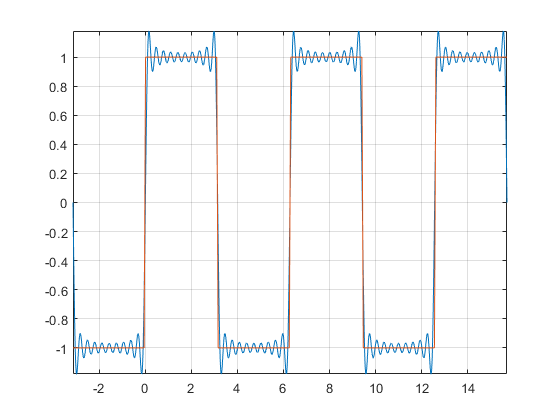

x = linspace(-pi, pi, 100); %% first evaluate the function in its actual intervals
y = f(x);
ry = repmat(y, 1, 3);
rx = linspace(-pi, 5*pi, length(ry));
plot(rx, ry);
grid on;
hold off;